# Measuring transcriptional elongation rate in live *Drosophila melanogaster* embryos

We'll start by opening up a single image and measuring the number of active transcriptional loci (Green dots below. Red is a nuclear RFP-histone marker. ) within that image. Afterwards, we'll program a for loop to do the same for all the images and produce graphs of the number of actively transcribing loci over time. We'll find that this is an accurate measure of the RNA Pol II elongation rate.

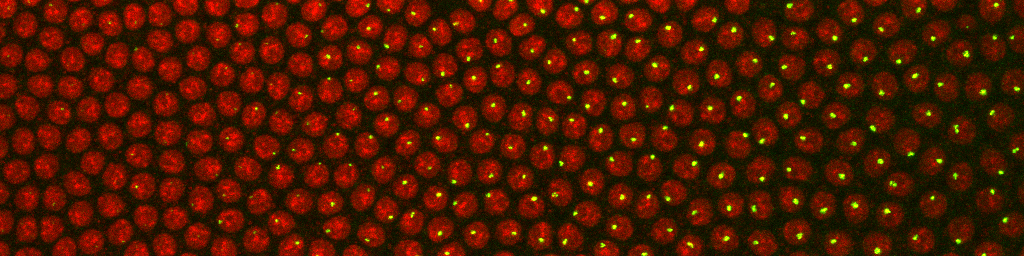

Open up live script by hitting home -> new -> live script. you can switch to in line figures by hitting the little icon in the top right corner of the window. Add text or new sections by hitting Live Editor -> Text or Live Editor -> Section Break, respectively. 

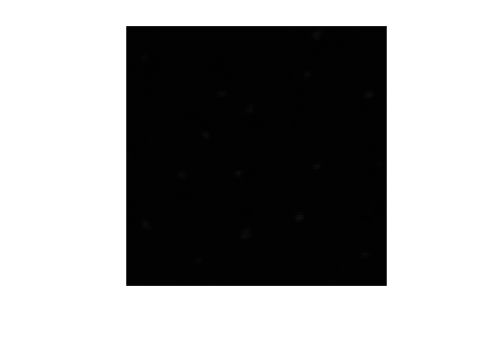


%Load frame 5' movie frame 189
Image = imread('5Loops0189.tif');
%The semicolon suppresses output in the command window. 
imshow(Image);


%We get a black square. Why?
whos Image      %Get information about the data stored in a variable

  Name         Size             Bytes  Class     Attributes

  Image      128x128            32768  uint16              



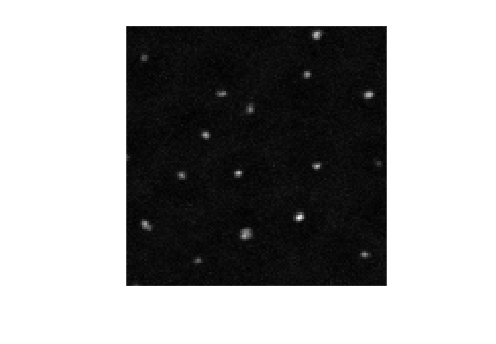


%Note that our image is a 16-bit image with 2^16 levels of gray. However,
%Matlab (and your screen) can only display 256 levels of gray. We need to
%tell Matlab how to map the different levels. An approach could be to grab
%the dimmest pixel, set it to 0, and grab the brightest pixel, and set it
%to 1.
imshow(Image,[])

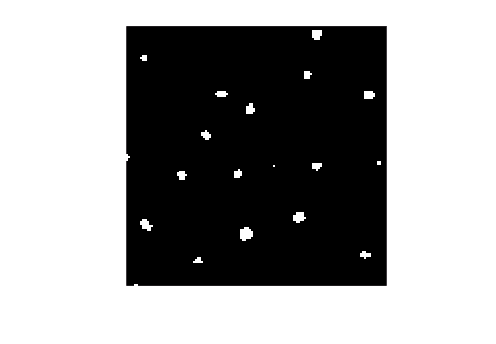


%Find a threshold by inspecting the pixel values using imtool
%imtool(Image,[])
Threshold=1000;

%Take the threshold
ImThresh=Image>Threshold;
imshow(ImThresh)

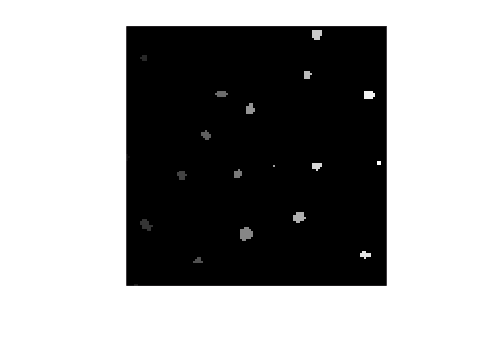


%Label the connected regions in the image
ImLabel=bwlabel(ImThresh);
imshow(ImLabel,[])

%imtool(ImLabel,[])

%To find the number of spots, we find the maximum value corresponding to
%regions in the labeled image
NSpots=max(max(ImLabel))

NSpots = 19

## Measuring the number of transcribing loci in the entire 5' movie

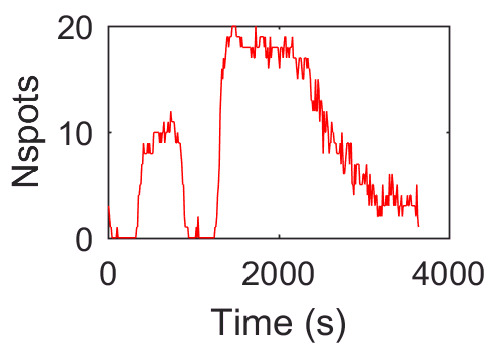

%Analyze the 5' movie
%Get the images in the folder
D5=dir('5Loops*.tif');

%Segment each image and count spots
for i=1:length(D5)
    %Load the image
    Image=imread(D5(i).name);
    %Take the threshold
    ImThresh=Image>Threshold;
    %Find spots
    ImLabel=bwlabel(ImThresh);
    %Count spots
    NSpots5(i)=max(max(ImLabel));
end
Time5=(1:length(D5))*10;        %In seconds. 
%Time resolution is 10s between images.
plot(Time5,NSpots5,'-r')
xlabel('Time (s)')
ylabel('Nspots')

## Measuring the number of transcribing loci in the entire 3' movie and overlaying the plots

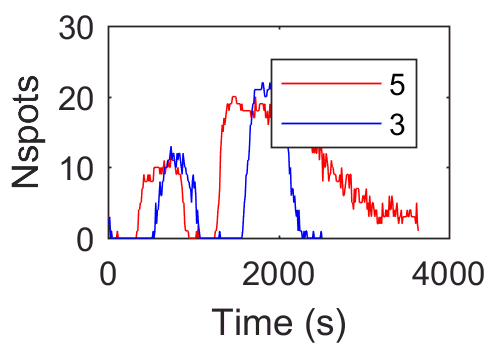


%Analyze the 3' movie
%Get the images in the folder
D3=dir('3Loops*.tif');

%Segment each image and count spots
for i=1:length(D3)
    %Load the image
    Image=imread(D3(i).name);
    %Take the threshold
    ImThresh=Image>Threshold;
    %Find spots
    ImLabel=bwlabel(ImThresh);
    %Count spots
    NSpots3(i)=max(max(ImLabel));
end
Time3=(1:length(D3))*10;        %In seconds

hold on
plot(Time3,NSpots3,'-b')
hold off
legend('5','3')

You can hover your mouse over the figure to pop the image out of the live script window and then maximize it. Once youv'e done that, you can use the "Data Cursor" button to hover over data points in the image to measure the gap between 5' loci appearance and 

3' loci appearance. This duration divided by the length of the gene (6 kbp) gives the elongation rate. 